# Tutoriel Analyse Musculosquelettique

**Auteur: Charles Pontonnier, Ecole Normale Supérieure de Rennes**

Dans le tutoriel suivant, nous allons procéder à l'analyse musculosquelettique de fentes d'escrime.

Nous allons particulièrement investiguer deux questions principales:

a.  quelle adaptation réalise l'escrimeur au cours de sa fente, lorsque la cible change ?

b. quel couple l'escrimeur développe-t-il au niveau du genou d'appui lors de la fente ?

clear all
close all
clc

# Présentation de l'expérimentation

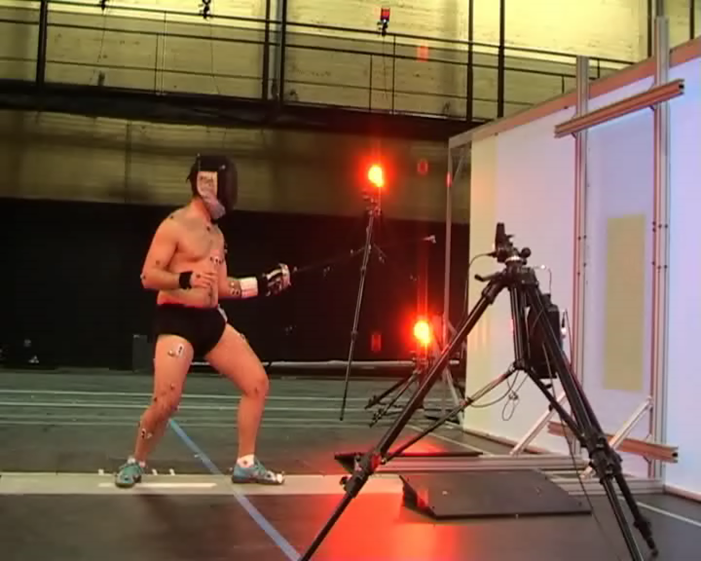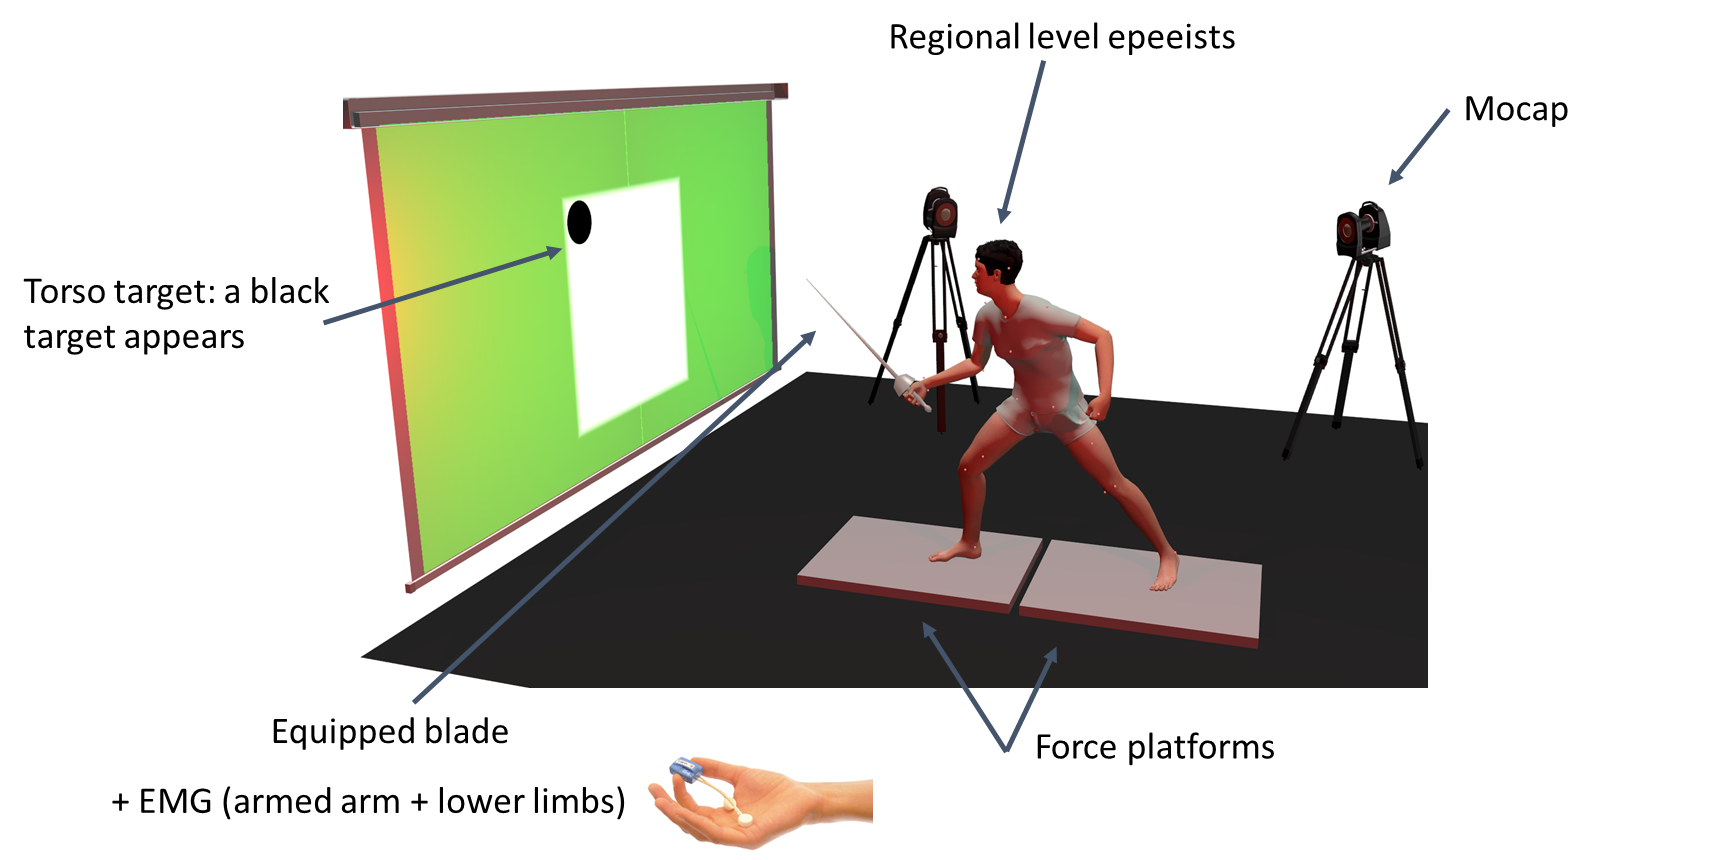

L'expérimentation consiste en une série d'essais de touche sur une cible virtuelle représentant un plastron. Lors de ces expérimentations, nous avons joué sur la nature des cibles apparaissant sur le plastron, elles pouvaient parfois être fixes, parfois mobiles, parfois incertaines (susceptibles d'être mobiles). Nous investiguions dans ce cadre la réponse des épéistes face à l'incertitude. Les données expérimentales utilisées dans ce tutoriel sont issues de ces expérimentations. Les études découlant de cette expérimentation sont disponibles dans les publications suivantes:

[Sorel, A., Plantard, P., Bideau, N., & Pontonnier, C. (2019). Studying fencing lunge accuracy and response time in uncertain conditions with an innovative simulator. Plos One, 14(7), e0218959.](https://journals.plos.org/plosone/article?id=10.1371/journal.pone.0218959) 

[Plantard, P., Sorel, A., Bideau, N., & Pontonnier, C. (2017). Motion adaptation in fencing lunges: a pilot study. Computer methods in biomechanics and biomedical engineering, 20(sup1), S161-S162.](https://www.tandfonline.com/doi/full/10.1080/10255842.2017.1382912)

[Pontonnier, C., Livet, C., Muller, A., Sorel, A., Dumont, G., & Bideau, N. (2019). Ground reaction forces and moments prediction of challenging motions: fencing lunges. Computer methods in biomechanics and biomedical engineering, 22(sup1), S523-S525.](https://www.tandfonline.com/doi/full/10.1080/10255842.2020.1715005)

# Configuration du tutoriel

Exécuter la ligne de commande suivante afin de configurer Matlab pour la suite du tutoriel (installation des librairies d'analyse BTK et CusToM)

 cd CusToM
 Installation

Your Matlab version 9.11.0.1837725 (R2021b) Update 2 is compatible with CusToM
 All the required Toolboxes are installed to run CusToM
    {'Optimization Toolbox'      }
    {'Parallel Computing Toolbox'}
    {'Robotics System Toolbox'   }
    {'Signal Processing Toolbox' }
    {'DSP System Toolbox'        }

The functions folder has been added to the current path
You can run a Simulation into the Examples folder or follow the written tutorials in the CusToM documentation


 cd ..

# Nature des données

Le tutoriel s'intéresse à l'analyse de 3 fichiers de type C3D (format unifié des données de capture de mouvement): 1 essai "Range of Motion" (**ROM001.c3d**) où le sujet réalise des mouvements fonctionnels permettant la calibration des modèles, et 2 essais de fente du type de ceux décrits ci-dessus (**Trial010.c3d **et **Trial011.c3d**). Des vidéos des essais sont également disponibles.

Les fichiers contiennent des données de différente nature: des trajectoires de marqueurs de capture de mouvement, des données de plateforme de force ainsi que des données EMG.

Pour illustrer la nature de ces données, nous allons les ouvrir et investiguer leur évolution au cours du temps.

## Trajectoires de marqueurs

%ouverture du fichier C3D
acq = btkReadAcquisition('Trial010.c3d');
%récupération des données de capture de mouvement en mm
markers = btkGetMarkers(acq);
%récupération des données de la fréquence d'acquisition de la capture de
%mouvement en Hz
f_mocap=btkGetPointFrequency(acq)

f_mocap = 250

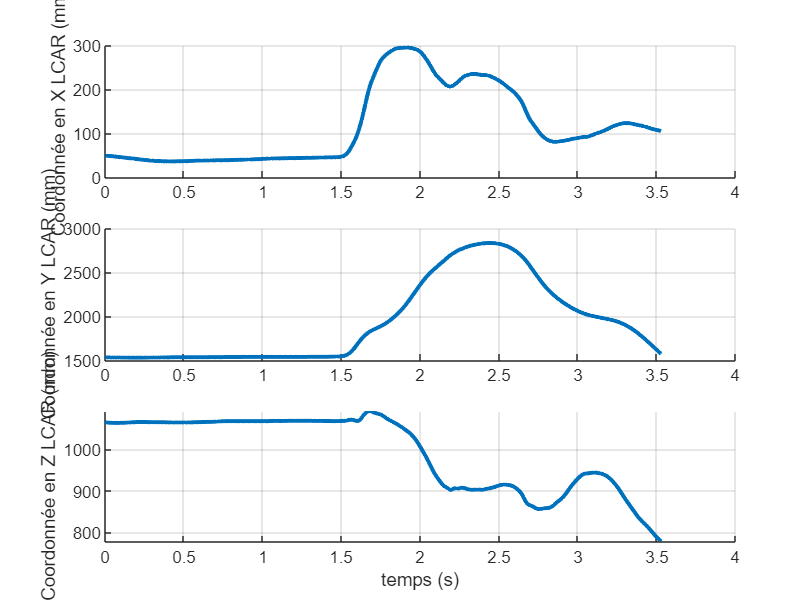

n_frames=numel(markers.LCAR(:,1));
%reconstruction donnée temps capture de mouvement
t_mocap=0:1/f_mocap:(n_frames-1)/f_mocap;
%reconstruction

%tracé du mouvement du marqueur de la main armée (LCAR)
figure 
subplot(3,1,1)
hold on
grid on
plot(t_mocap,markers.LCAR(:,1),'LineWidth',2);
ylabel('Coordonnée en X LCAR (mm)')
subplot(3,1,2)
hold on
grid on
plot(t_mocap,markers.LCAR(:,2),'LineWidth',2);
ylabel('Coordonnée en Y LCAR (mm)')
subplot(3,1,3)
hold on
grid on
plot(t_mocap,markers.LCAR(:,3),'LineWidth',2);
ylabel('Coordonnée en Z LCAR (mm)')
xlabel('temps (s)')

**QUESTION 1 : tracez la position au cours du temps du marqueur sur le gros orteil gauche (LTOE)**

%% TODO : tracer le mouvement du marqueur avant du pied gauche (LTOE)
%% Exploiter la même syntaxe que celle proposée ci-dessus


A présent nous allons dériver la position du marqueur LCAR pour obtenir la vitesse de translation de la main au cours du temps.

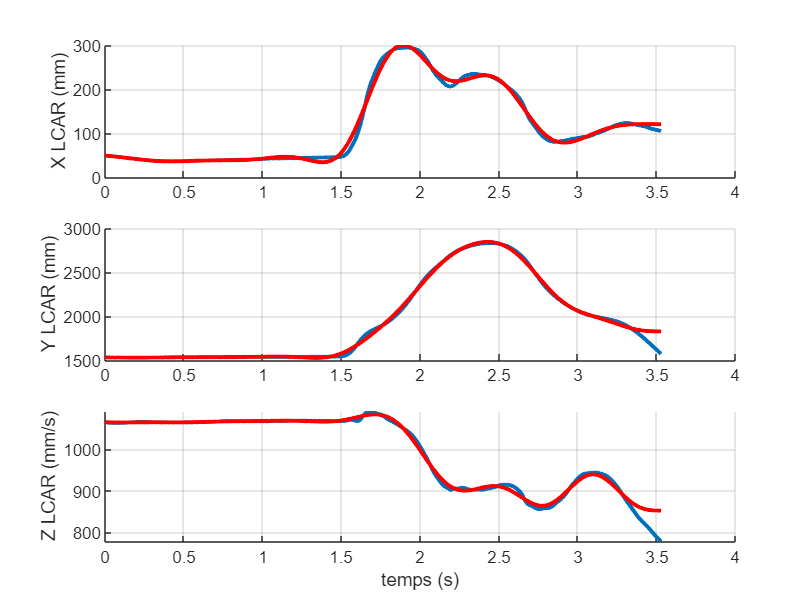

% Dérivation du marqueur LCAR actuellement à 2Hz
%modifier le 2ème argument pour modifier la fréquence de coupure
FLCAR=filt_data(markers.LCAR,2,f_mocap);
VLCAR=derivee2(1/f_mocap,markers.LCAR);
VFLCAR=derivee2(1/f_mocap,FLCAR);

%tracé du mouvement du marqueur de la main armée (LCAR) avec ou sans filtre

figure 
subplot(3,1,1)
hold on
grid on
plot(t_mocap,markers.LCAR(:,1),'LineWidth',2);
plot(t_mocap,FLCAR(:,1),'r','LineWidth',2);
ylabel('X LCAR (mm)')
subplot(3,1,2)
hold on
grid on
plot(t_mocap,markers.LCAR(:,2),'LineWidth',2);
plot(t_mocap,FLCAR(:,2),'r','LineWidth',2);
ylabel('Y LCAR (mm)')
subplot(3,1,3)
hold on
grid on
plot(t_mocap,markers.LCAR(:,3),'LineWidth',2);
plot(t_mocap,FLCAR(:,3),'r','LineWidth',2);
ylabel('Z LCAR (mm/s)')
xlabel('temps (s)')

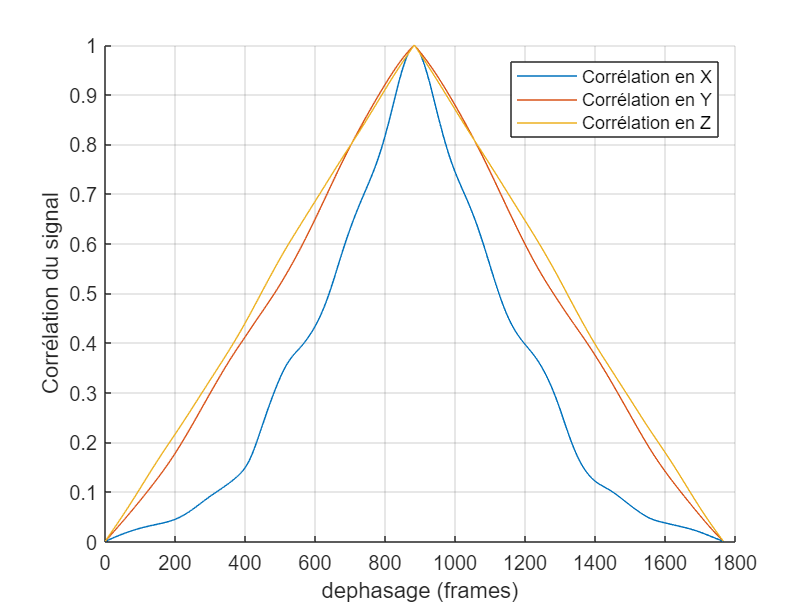



% corrélation des signaux filtrés et non filtrés
[corrx,delx]=xcorr(markers.LCAR(:,1),FLCAR(:,1),'normalized');
[corry,dely]=xcorr(markers.LCAR(:,2),FLCAR(:,2),'normalized');
[corrz,delz]=xcorr(markers.LCAR(:,3),FLCAR(:,3),'normalized');
figure
hold on
grid on
plot(corrx);
plot(corry);
plot(corrz);
ylabel('Corrélation du signal')
xlabel('dephasage (frames)')
legend({'Corrélation en X','Corrélation en Y','Corrélation en Z'})

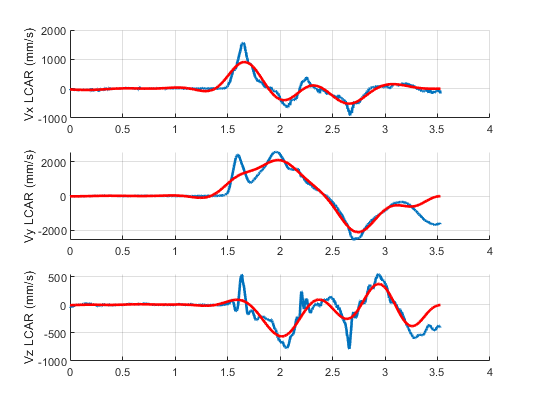


% tracé des vitesses à partir de la dérivée du signal brut et filtré
figure 
subplot(3,1,1)
hold on
grid on
plot(t_mocap,VLCAR(:,1),'LineWidth',2);
plot(t_mocap,VFLCAR(:,1),'r','LineWidth',2);
ylabel('Vx LCAR (mm/s)')
subplot(3,1,2)
hold on
grid on
plot(t_mocap,VLCAR(:,2),'LineWidth',2);
plot(t_mocap,VFLCAR(:,2),'r','LineWidth',2);
ylabel('Vy LCAR (mm/s)')
subplot(3,1,3)
hold on
grid on
plot(t_mocap,VLCAR(:,3),'LineWidth',2);
plot(t_mocap,VFLCAR(:,3),'r','LineWidth',2);
ylabel('Vz LCAR (mm/s)')

**Question 2: modifiez la fréquence de filtrage pour trouver un filtrage adapté à la tache.**

## Données de plateforme de force

A présent nous allons tracer les données issues des plateformes de force pour en comprendre le contenu

%récupération des données de plateforme et des données EMG
Analogs = btkGetAnalogs(acq);
f_analog=btkGetAnalogFrequency(acq)

f_analog = 1000

n_frames_analog=numel(Analogs.Force_Fx1);
%reconstruction donnée temps signaux analogiques
t_analog=0:1/f_analog:(n_frames_analog-1)/f_analog;


**Question 3 : Tracez la force appliquée sur la plateforme n°1**

%% TODO explorer la structure "Analogs" et trouver les signaux souhaités
%% Tracer ces signaux en fonction du temps


## Données EMG

On regarde la nature de la donnée EMG et on applique un filtre (moyenne quadratique glissante ou "RMS").

%% tracé des données du rectus femoris (normalisé)
figure
hold on
grid on
plot(t_analog,Analogs.Voltage_R_RF,'LineWidth',2);

**Question 4: Modifier la valeur de la fenetre glissante pour obtenir un signal EMG filtré exploitable. Les recommandations pour les signaux dynamiques évoluent entre 40ms et 200ms pour les membres inférieurs, en fonction de la dynamique du mouvement étudié.**

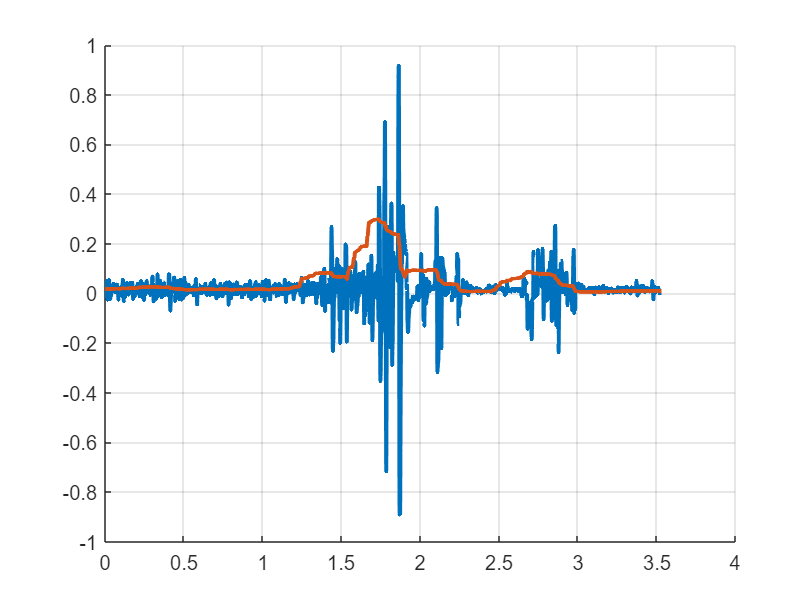

%% TODO RMS sur le signal à 200ms 
sliding_window=200e-3;
RF_RMS = EMG_RMS(Analogs.Voltage_R_RF,sliding_window*f_analog);
plot(t_analog,RF_RMS,'LineWidth',2);